# Exercise 1

## Exercise 1.1

clear all;
clc;
close all;

% Setup parameters for Problem
sim_name = 'concentration_1_1';
plt_title = 'numerical vs analytical solution 1.1';
h = 1;
N = 100;
dt = 0.00004;
numberSteps = 1000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% Set boundary condition at x=0
C(1) = 1;

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_explicit(C,s,1);
    
    if makeVideo && mod(i,30)==0
        C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params, C_analytic)
    end
    
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


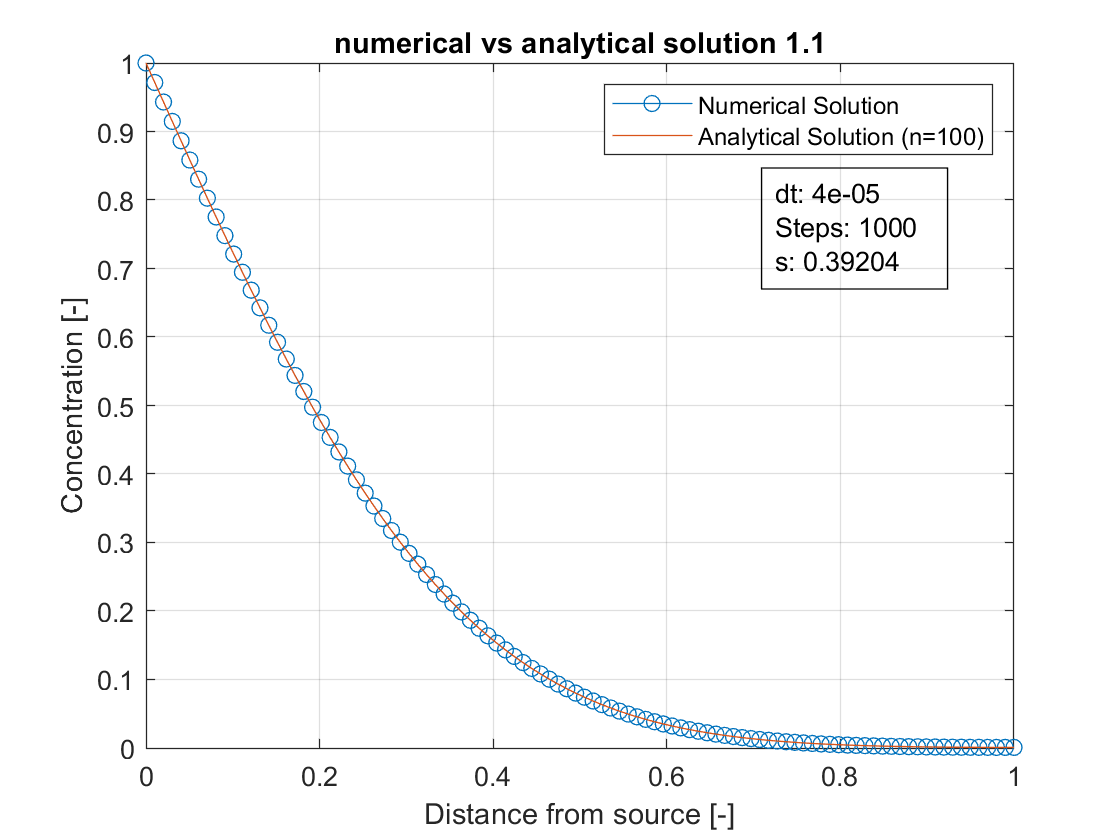


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_analytic);

## Exercise 1.2

clear all;
clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_2';
plt_title = 'numerical solution 1.2';
h = 1;
N = 100;
dt = 0.00005;
numberSteps = 10000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2;

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
% Set boundary condition at x=0
C(1) = 1;
% Set boundary condition at x=h
C(end) = 0;
if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_explicit(C,s,2);
    
    if makeVideo && mod(i,30)==0
        %C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params)%, C_analytic)
    end
    
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


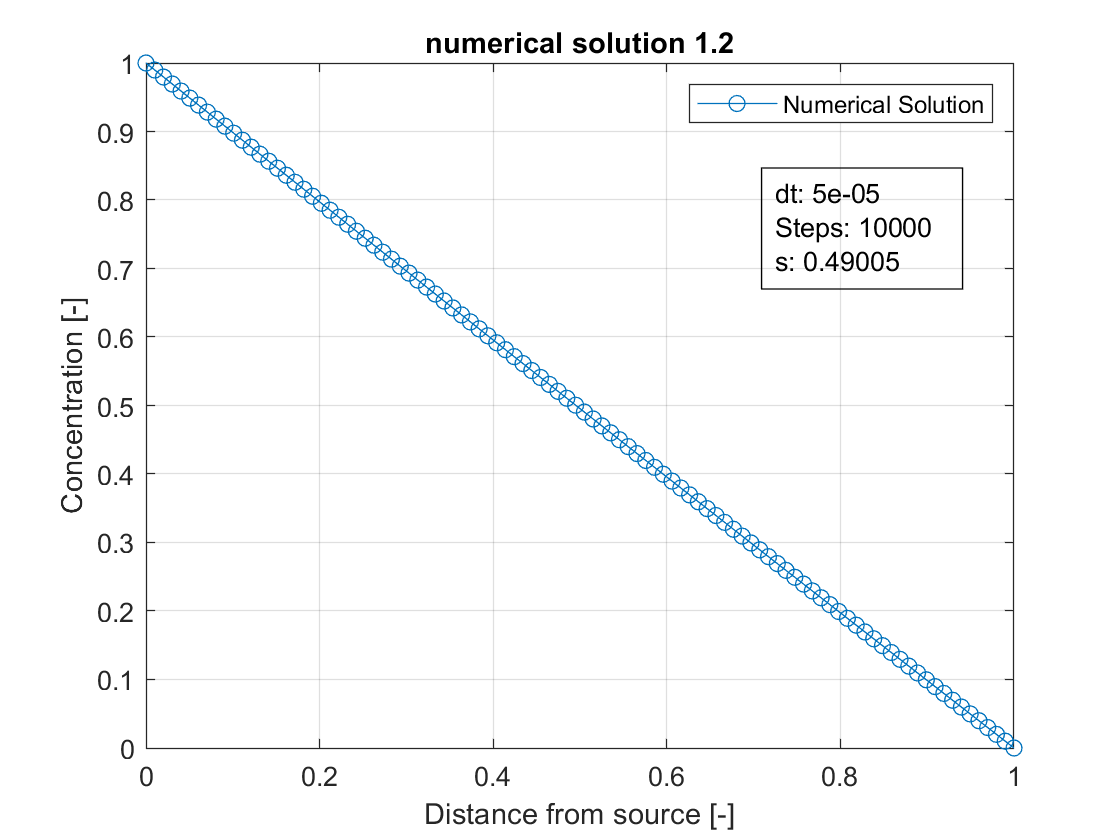


try
    close(v);
end

% Plot final solution
%C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params)%, C_analytic);

## Exercise 1.3

clear all;
clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_3';
plt_title = 'numerical solution 1.3'

plt_title = 'numerical solution 1.3'

h = 1;
N = 100;
dt = 0.0005;
numberSteps = 1000;
makeVideo = false;

dx = h/(N-1);
s = dt/dx^2

s = 4.9005


% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);

% Diagonal for update matrix
diag = ones(1,N-1)*(1+2*s);
lower = ones(2,N-1)*(-s); % lower diag
upper = ones(1,N-1)*(-s); % upper diag
% Setup boundary condition at x=0
C(1) = 1;
diag(1) = 1; % ==Keep C(1) always the same
upper(1) = 0; % ==Keep C(1) always the same
% Setup boundary condition at x=h
diag(end) = 1+s; % ==Keep C(end) always the same

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

% SIMULATION
start = now();
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_implicit_new(C, N, diag, lower, upper);
    %C = makeTimeStep_implicit(C, s);
    if makeVideo && mod(i,30)==0
        %C_analytic = analyticalSolution(N,100,i*dt);
        writeFrame(v, C, x, i, sim_params)%, C_analytic)
    end
    
end

10.00 %
20.00 %
30.00 %
40.00 %
50.00 %
60.00 %
70.00 %
80.00 %
90.00 %
100.00 %


runtime = now() - start

runtime = 8.1409e-07

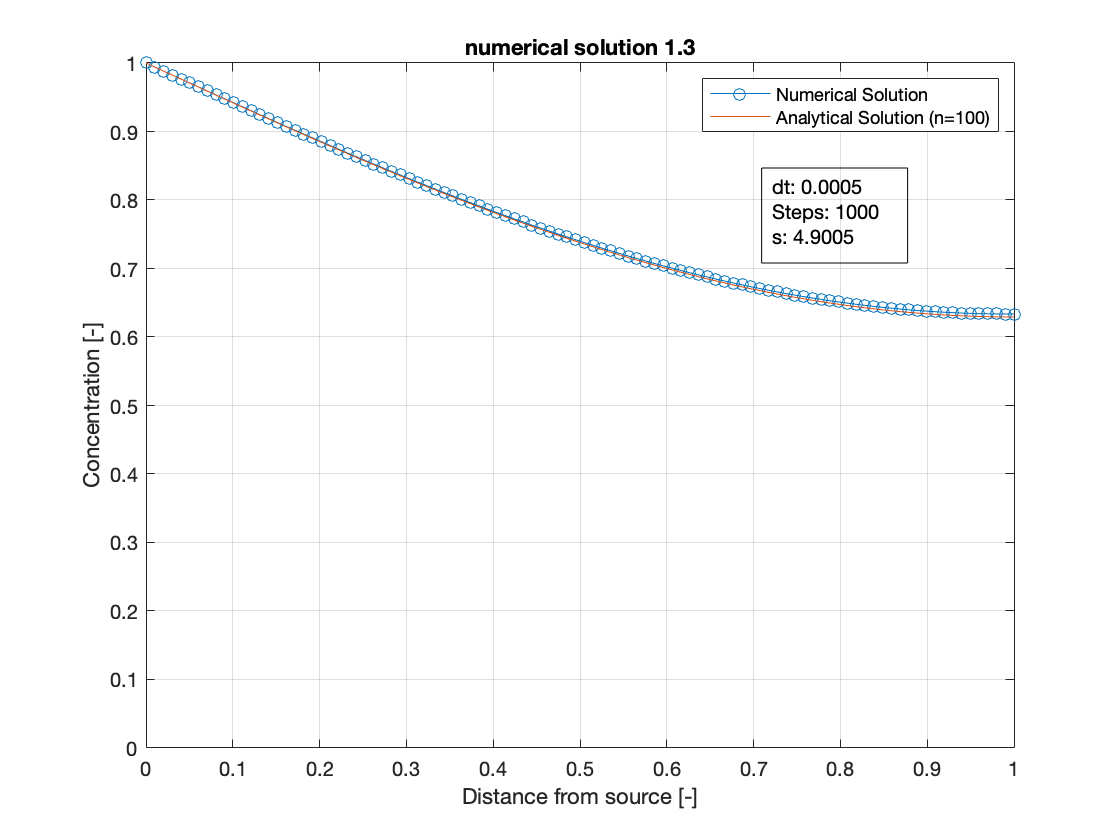

try
close(v);
end

% Plot final solution
C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_analytic);

C_1_3 = C;

## Exercise 1.4

%clear all;
%clc;
close all;
% Setup parameters for Problem
sim_name = 'concentration_1_4_halftime'; % name for movie
plt_title = 'numerical solution 1.4'

plt_title = 'numerical solution 1.4'

h = 1;
N = 100;
dt = 0.0005 * 0.5;
numberSteps = 1000;
makeVideo = true;

dx = h/(N-1);
s = dt/dx^2

s = 2.4502


% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = s; 
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

% Setup vectors/arrays
x = linspace(0,h,N);
C = zeros(1,N);
C_check = zeros(1,N);

% Diagonal for update matrix
diag = ones(1,N-1)*(1+2*s);
% Modified diagonal
% diag = ones(1,N-1)*2*(1+s);
lower = ones(2,N-1)*(-s); % lower diag
upper = ones(1,N-1)*(-s); % upper diag

% Set boundary condition at x=0
C(1) = 1;
diag(1) = 1; % ==Keep C(1) always the same
upper(1) = 0; % ==Keep C(1) always the same
% Set boundary condition at x=h
diag(end) = 1+s; % ==Keep C(1) always the same

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end


% M = zeros(N);
% M(  1:1+N:N*N) = 1+2*s;
% M(N+1:1+N:N*N) = -s;
% M(  2:1+N:N*N-N) = -s;
% M(N-1,N-1) = 1+s;
% M(1,1) = 1;
% M(1,2) = 0;
% M = M(1:N-1,1:N-1);

% SIMULATION
start = now();
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    
    C = makeTimeStep_CrankNicolson(C, diag, lower, upper, sim_params);
%     C_check_iminus1 = [C_check;0];
%     C_check_iplus1 = [0;C_check];
%     C_check = s*C_check_iminus1(1:end-1) + (1-2*s)*C_check + s*C_check_iplus1(2:end);
%     C_check(1:end-1) = M\C_check(1:end-1);
%     C_check(end) = C_check(end-1);
    
    if makeVideo && mod(i,30)==0
        C_analytic = analyticalSolution(N,100,i*dt*2);
        writeFrame(v, C, x, i, sim_params, C_analytic)
    end  
end

10.00 %


20.00 %


30.00 %


40.00 %


50.00 %


60.00 %


70.00 %


80.00 %


90.00 %


100.00 %


runtime = now() - start

runtime = 1.5342e-04

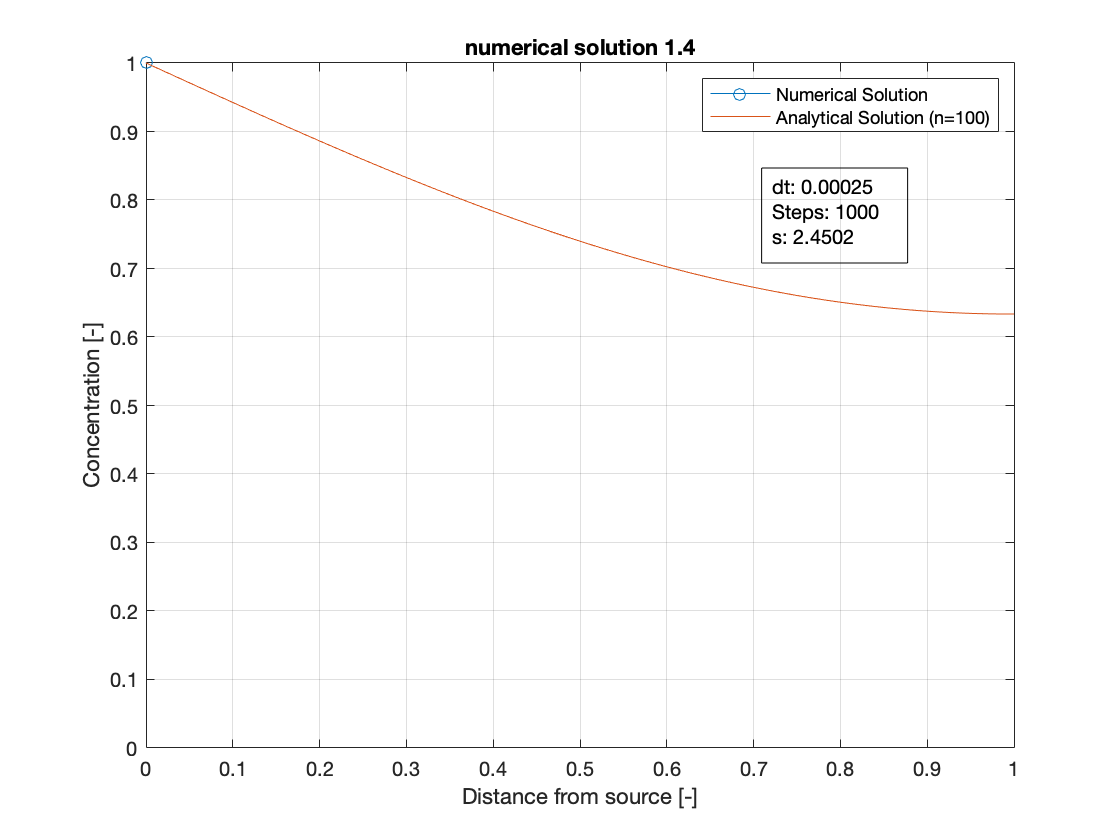


try
close(v);
end

% Plot final solution
%C_analytic = analyticalSolution(N,100,numberSteps*dt);
plotConcentration(x, C, sim_params, C_1_3);

#### A note on the Crank-Nichelson-Algorithm:

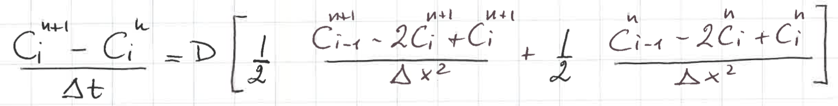

according to lecure should be:


$$\frac{C_i^{n+1} - C_i^n}{\Delta t} = \frac{D}{2} \left ( \frac{C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1}}{\Delta x^2}  + \frac{C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1}}{\Delta x^2} \right)$$


$D=1$ for simplicites sake


$$\Delta t / \Delta x^2 = s$$



$$2 (C_i^{n+1} - C_i^n) = s \dot \left ( C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1} + C_{i-1}^{n+1} - 2 C_i^{n+1} + C_{i-1}^{n+1} \right)$$


After rearranging, however, I get this:


$$- s C_{i-1}^{n+1} + 2(1+s) C_i^{n+1}  -  s C_{i-1}^{n+1} = s C_{i-1}^{n} + 2(1-s) C_i^{n} + s C_{i-1}^{n}$$


Hmm...thats a bit different. It also doesn't work :D

## Exercise 2.1

clear all;
clc;
close all;

sim_name = 'concentration_2_1_square';
plt_title = 'numerical solution 2.1.square';
h = 1;
N = 101;
dt = 0.012;
numberSteps = 100;
makeVideo = true;

dx = 1/(N-1);

% Pack into struct for convenience later
sim_params = struct; 
sim_params.h = h; sim_params.N = N;
sim_params.dt = dt; sim_params.dx = dx; sim_params.s = 0;
sim_params.numberSteps = numberSteps; sim_params.makeVideo = makeVideo;
sim_params.plt_title = plt_title;

x = linspace(0,h,N);
C = zeros(1,N);
for i = 0:1:100
    if (i > 10 & i < 30)
        C(i) = 1;
    end
end
Cstart = C;

if makeVideo
    v = VideoWriter(sim_name);
    open(v);
end

C0 = dt/dx;
for i = 1:numberSteps
   if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_upwind(C,C0);
    
    if makeVideo
        C_analytic = analyticalSolutionAdvection(Cstart,i);
        writeFrame(v, C, x, i, sim_params, C_analytic, [-1 2])
    end
    
end

10.00 %


20.00 %


30.00 %


40.00 %


50.00 %


60.00 %


70.00 %


80.00 %


90.00 %


100.00 %


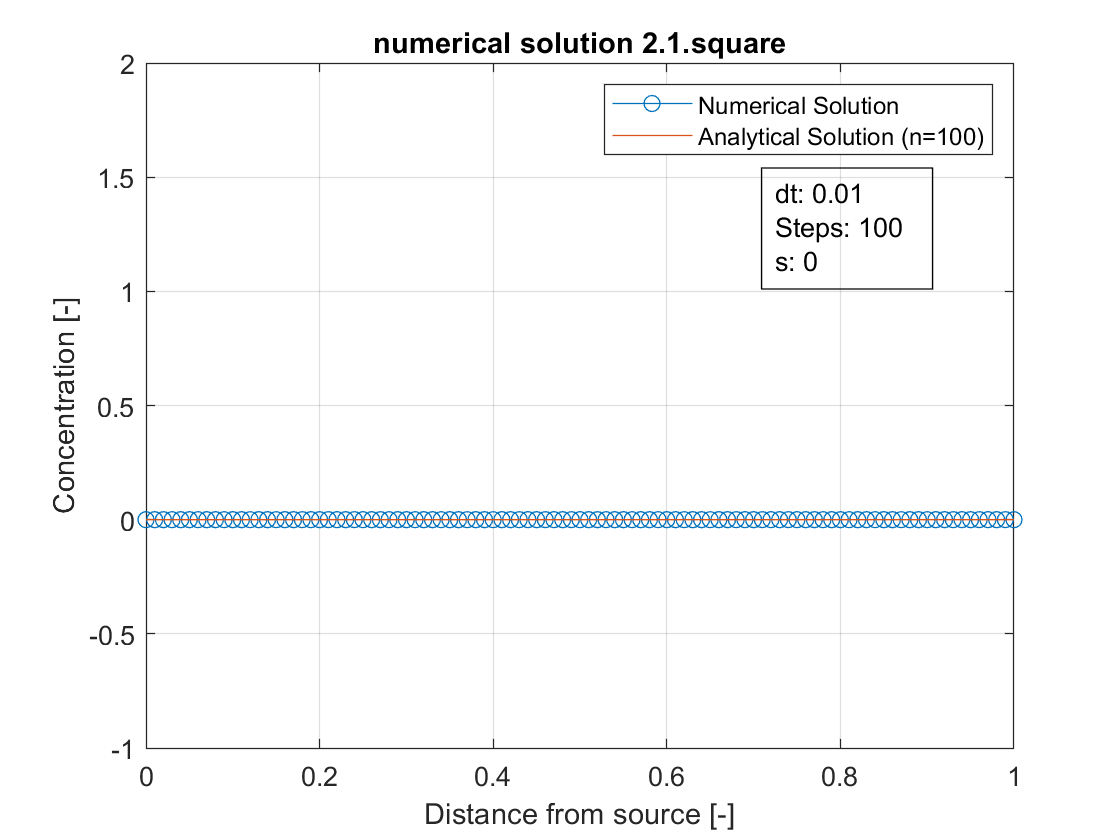

10.00 %


20.00 %


30.00 %


40.00 %


50.00 %


60.00 %


70.00 %


80.00 %


90.00 %


100.00 %



try
close(v);
end

% Plot final solution
C_analytic = analyticalSolutionAdvection(Cstart,numberSteps);
plotConcentration(x, C, sim_params, C_analytic, [-1 2]);


%% part two

t = x;
C = exp(-10.*(4.*t-1).^2);
Cstart = C;

if makeVideo
    v = VideoWriter('concentration_2_1_gauss');
    open(v);
end

C0 = dt/dx;
for i = 1:numberSteps
    if mod(i,numberSteps/10)==0
        % Display i every 10% of numberSteps
        text1= sprintf('%.2f %%', i/numberSteps*100);
        disp(text1);
    end
    C = makeTimeStep_upwind(C,C0);
    
    if makeVideo
        C_analytic = analyticalSolutionAdvection(Cstart,i);
        writeFrame(v, C, x, i, sim_params, C_analytic, [-1 2])
    end
    
end

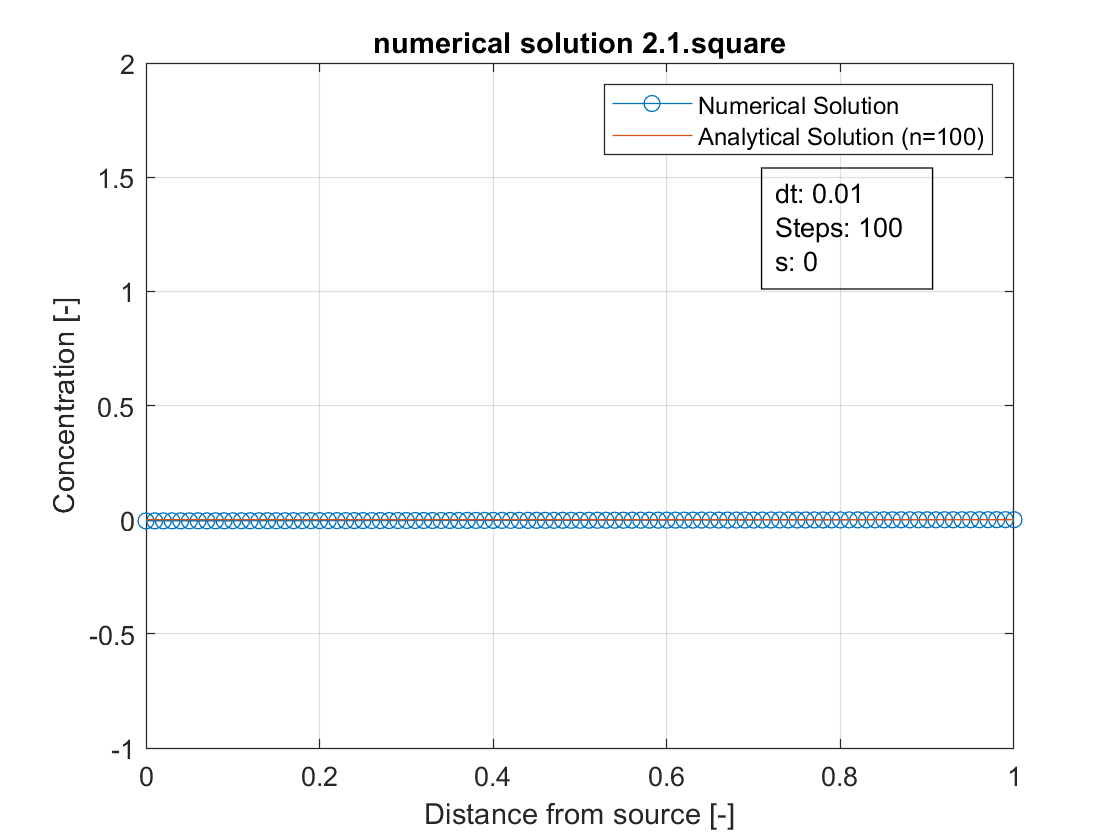


try
close(v);
end

% Plot final solution
C_analytic = analyticalSolutionAdvection(Cstart,numberSteps);
plotConcentration(x, C, sim_params, C_analytic, [-1 2]);